# Model the Heat Tolerance of Components Exposed to Electronics

This finite element thermal analysis (FEA) examines the heat tolerance for a robotics component of a commercial youBot.

A single domain heat conduction analysis is performed on the nearest robotic component to the heat producing circuit board.  The analysis is then extended to perform a Design of Experiment analysis to model temperature as a function of thermal conductivity. 

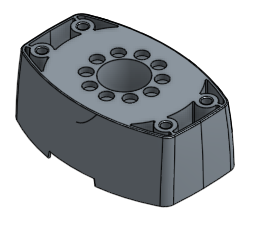     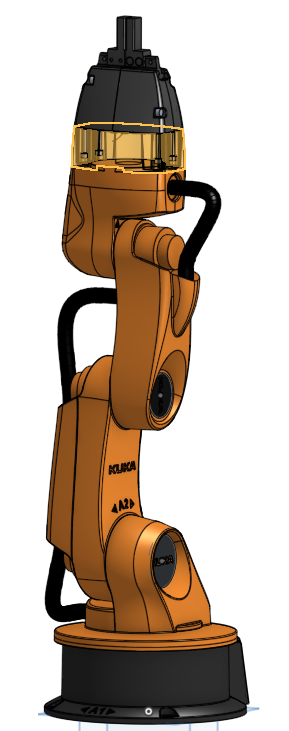      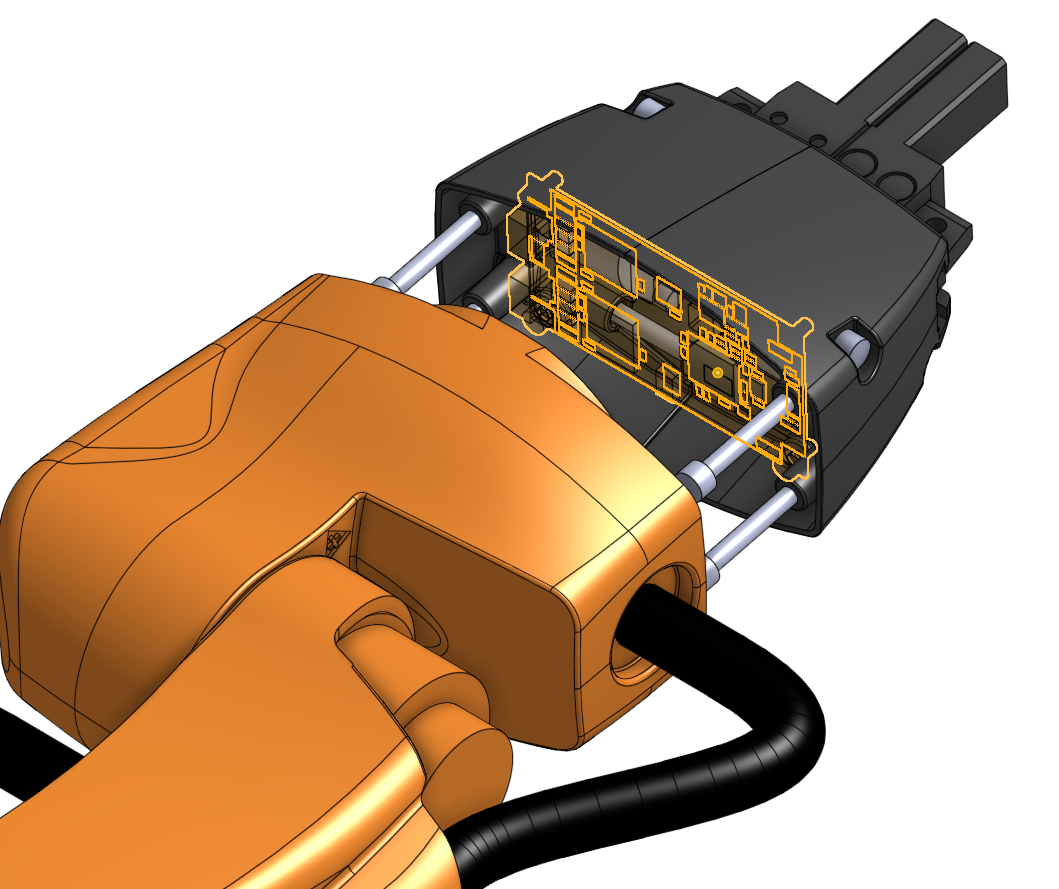

Figures : Gripper Pivot (left), youBot with pivot highlighted (middle) and circuit board (right)

Products used in this demo include

- **PDE Toolbox** for the finite element thermal analysis (FEA).  

- **Symbolic Math Toolbox** for unit conversions. 

- **Parallel Toolbox** for multiple analysis runs.

- **Statistics and Machine Learning Toolbox** for linear fitting. 

References : 

- What is a [youBot](http://www.youbot-store.com/)?

- Simscape Multibody [youBot simulation](https://www.mathworks.com/matlabcentral/fileexchange/61370-robot-arm-with-conveyor-belts).

This example requires **R2017a** or newer.

## Import the geometry

In the youBot the gripper pivot  sits underneath the electronics board and is exposed to the heat coming off the circut board. Here we will create the pde model, import the STL file of the gripper pivot, and plot it.

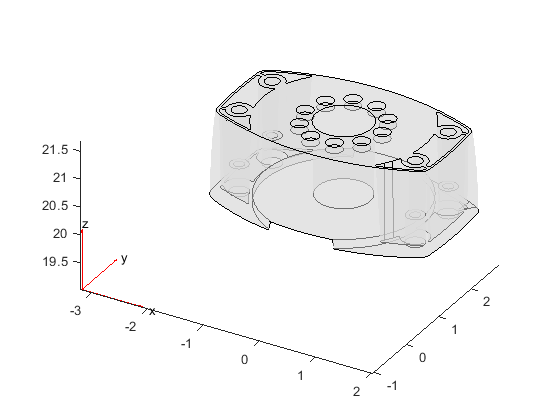

thermalmodel = createpde('thermal','steadystate');
importGeometry(thermalmodel,'Gripper Pivot.stl');
pdegplot(thermalmodel, 'FaceAlpha',0.5)

## Mesh the Geometry and Determine the Part size

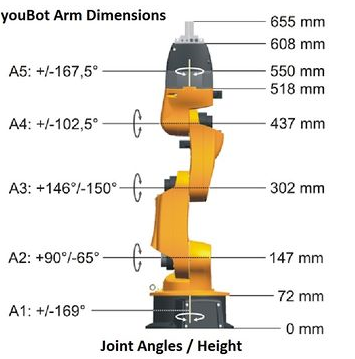                               

From the supplied dimensions above we can estimate the part height should be approximatly 32mm or 1.2598in.  However, we can see from the above `pdegplot` that the imported geometry is likely dimensioned in inches and not mm. Create and visualize a tetrahedral mesh of the component with a maximum value of 0.09 inches.

generateMesh(thermalmodel,'Hmax',0.09);
thermalmodel.Mesh

ans =   FEMesh with properties:

             Nodes: [3×169932 double]
          Elements: [10×112364 double]
    MaxElementSize: 0.0900
    MinElementSize: 0.0450
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'

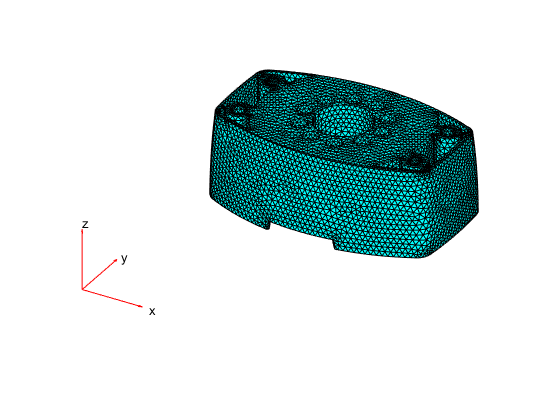

pdemesh(thermalmodel)

Measure the dimensions of the mesh. The part height is in fact 1.4606 inches.

xLength = max(thermalmodel.Mesh.Nodes(1,:)) - min(thermalmodel.Mesh.Nodes(1,:))

xLength = 4.0041

yLength = max(thermalmodel.Mesh.Nodes(2,:)) - min(thermalmodel.Mesh.Nodes(2,:))

yLength = 2.7180

zLength = max(thermalmodel.Mesh.Nodes(3,:)) - min(thermalmodel.Mesh.Nodes(3,:))

zLength = 1.4606

## Setup the Material Properties 

The material is assumed to be a magnesium alloy and to have a thermal conductivity of $52\text{ }\frac{W}{m\text{ }K}$. Material properties were taken from "Thermal Conductivity of Magnesium Alloys" [1].  Since the model is in inches we can use `symunit` to rewrite the value in inches. 

u = symunit;
tc = vpa(52) *u.Watt/(u.m*u.Kelvin)

$$tc = 52.0\,\frac{W}{K\,m}$$

tc = rewrite(tc,u.W/(u.in*u.Kelvin))

$$tc = 1.3208\,\frac{W}{K\,\mathrm{in}}$$

Now remove the units to obtain the value for the thermal properties. 

tc = double(separateUnits(tc));
thermalProperties(thermalmodel,'Cell',1,'ThermalConductivity',tc); 

## Set up the Boundary Conditions

The boundary conditions for this model are assumed, if more data was available we could improve the following assumptions.  

Unless overwritten, all of the side faces are set to have a natural convection coefficient of 25 $\frac{W}{m^2 K}$ representing heat transfer to an ambient air temperature of $288\ldotp 15K\text{ }\left(25C^{\circ } \right)$.  Convert the convection coefficient to $\frac{W}{{in}^2 K}$ to be consistent with the model dimensions.

htc = vpa(25) *u.Watt/(u.m^2*u.Kelvin);
htc = rewrite(htc,u.Watt/(u.in^2*u.Kelvin));
htc = double(separateUnits(htc));
thermalBC(thermalmodel,'Face',1:thermalmodel.Geometry.NumFaces,...
        'ConvectionCoefficient',htc,'AmbientTemperature',288.15);

The bottom face is given a fixed temperature assuming that the rest of the robotic arm acts as a heat sink.

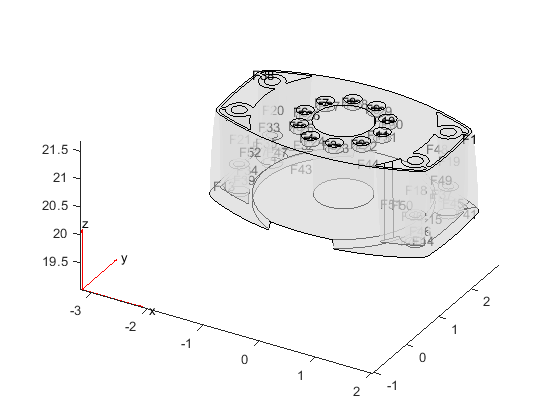

 pdegplot(thermalmodel,'FaceLabels','on', 'FaceAlpha',0.5)

thermalBC(thermalmodel,'Face',43,'Temperature',288.15);

The top face and inner hole is arbitrarily given a heat flux to represent the heat off the circuit board.  

thermalBC(thermalmodel,'Face',38,'HeatFlux',25);
thermalBC(thermalmodel,'Face',44,'HeatFlux',10);

## Solve the FEA analysis

Solve the model and calculate the max and bulk body temperatures. Time how long the solve takes.

tic
results = solve(thermalmodel);
time = toc

time = 16.3469

## Post-process the Results

Compute the max temperature in $K$ and rewrite that to $C^{\circ }$ or $F^{\circ }$ depending on your preference.

t_max = max(results.Temperature)

t_max = 312.8632

vpa(rewrite(t_max*u.Kelvin,u.Celsius,'Temperature','absolute'),5)

$$ans = 39.713\,\mathrm{{}^{\circ}C}$$

vpa(rewrite(t_max*u.Kelvin,u.Fahrenheit,'Temperature','absolute'),5)

$$ans = 103.48\,\mathrm{{}^{\circ}F}$$

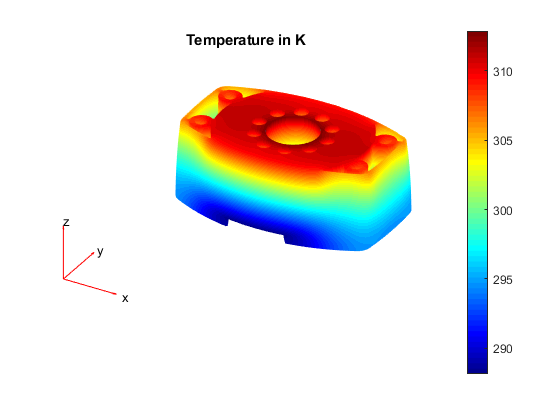

pdeplot3D(thermalmodel,'ColorMapData',results.Temperature)
title('Temperature in K')
colorbar

## Use Parallel Toolbox to Run Multiple Analysis

Explore different material selections for the robotic component. Compute the change in max body temperature as a function of increasing thermal conductivity.  

Before begining calculate the expected run time from the previous run time.

% Values from "Thermal Conductivity of Magnesium Alloys"[1] in W /(mK)
thermalConductivities = [45.3 51.2 63.2 76.9 83.5]; 
runtime = time * length(thermalConductivities)

runtime = 81.7347

Run the models using a [`parfor`](https://www.mathworks.com/help/distcomp/parfor.html) loop to speed up the simulation by parallelizing the iterations across Parallel Computing Toolbox workers.  If you do not have the Parallel Computing Toolbox `parfor` will run as a `for loop with no changes required to your code`. 

maxTemperatures = zeros(size(thermalConductivities)); 
thermalConductivities_inches = double(separateUnits(...
    rewrite(thermalConductivities *u.Watt/(u.m*u.Kelvin),u.W/(u.in*u.Kelvin)))); 
tic
parfor i = 1: length(thermalConductivities)
    thermalProperties(thermalmodel,'Cell',1,...
    'ThermalConductivity',thermalConductivities_inches(i)); 
    results = solve(thermalmodel);
    maxTemperatures(i) = max(results.Temperature)
end
tF = toc

tF = 54.9737

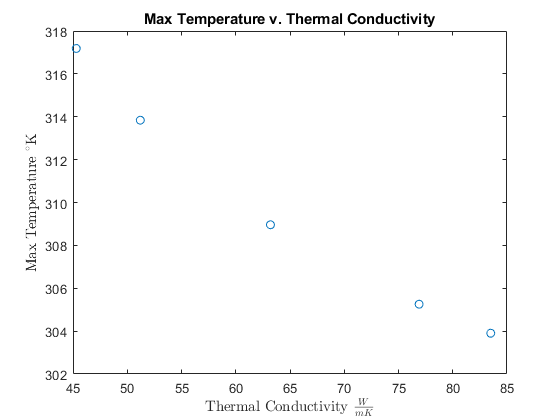

plot(thermalConductivities,maxTemperatures,'o')
xlabel('Thermal Conductivity $\frac{W}{mK}$','Interpreter','latex')
ylabel('Max Temperature $^\circ$K','Interpreter','latex')
title('Max Temperature v. Thermal Conductivity')

## Fit Model to Select Material Properties 

Since the relationship is linear, use [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html) to create a predictive model for the relationship between thermal conductivity and max temperature for this geometry and material. 

linearmodel = fitlm(thermalConductivities(:),maxTemperatures(:),'VarNames',...
    {'ThermalConductivity', 'MaxTemperature'})

linearmodel = Linear regression model:
    MaxTemperature ~ 1 + ThermalConductivity

Estimated Coefficients:
                           Estimate       SE        tStat       pValue  
                           ________    ________    _______    __________
    (Intercept)             331.72       1.9946     166.31    4.7932e-07
    ThermalConductivity     -0.342     0.030379    -11.258     0.0015028

Number of observations: 5, Error degrees of freedom: 3
Root Mean Squared Error: 0.989
R-squared: 0.977,  Adjusted R-Squared 0.969
F-statistic vs. constant model: 127, p-value = 0.0015

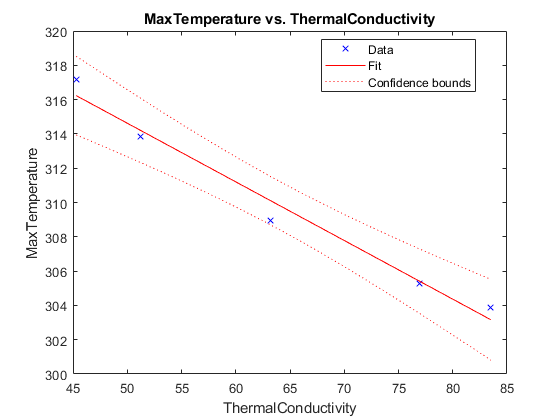

plot(linearmodel)

Assume the robotic arm shuts off at a max temperature of $311\text{ }K$, find the associated allowable heat transfer coefficient for the alloy. 

shutOffTemp = 311;
objective = @(x) predict(linearmodel,x) - shutOffTemp;
max_tc = fzero(objective,50)

max_tc = 60.5960

# Reference

- Lee, Ham, Kwon, Kim and Suh. "Thermal Conductivity of Magnesium Alloys". International Journal of Thermophysics. Jan 2012, 34-2343-2350. 

*Cop**yright MathWorks 2018*